# Scripts Metodos Numericos

x = [0 0.5 1]

x =          0    0.5000    1.0000


y = exp(sin(x))

y =     1.0000    1.6151    2.3198



p = lagrange(x,y)

p =     0.1790    1.1408    1.0000



xx = 0:0.01:1

xx =          0    0.0100    0.0200    0.0300    0.0400    0.0500    0.0600    0.0700    0.0800    0.0900    0.1000    0.1100    0.1200    0.1300    0.1400    0.1500    0.1600    0.1700    0.1800    0.1900    0.2000    0.2100    0.2200    0.2300    0.2400    0.2500    0.2600    0.2700    0.2800    0.2900    0.3000    0.3100    0.3200    0.3300    0.3400    0.3500    0.3600    0.3700    0.3800    0.3900    0.4000    0.4100    0.4200    0.4300    0.4400    0.4500    0.4600    0.4700    0.4800    0.4900


yy = polyval(p,xx)

yy =     1.0000    1.0114    1.0229    1.0344    1.0459    1.0575    1.0691    1.0807    1.0924    1.1041    1.1159    1.1277    1.1395    1.1513    1.1632    1.1751    1.1871    1.1991    1.2111    1.2232    1.2353    1.2475    1.2596    1.2719    1.2841    1.2964    1.3087    1.3211    1.3335    1.3459    1.3583    1.3708    1.3834    1.3960    1.4086    1.4212    1.4339    1.4466    1.4594    1.4721    1.4850    1.4978    1.5107    1.5236    1.5366    1.5496    1.5626    1.5757    1.5888    1.6020



x1 = 0.75

x1 = 0.7500

y1 = polyval(p,x1)

y1 = 1.9563

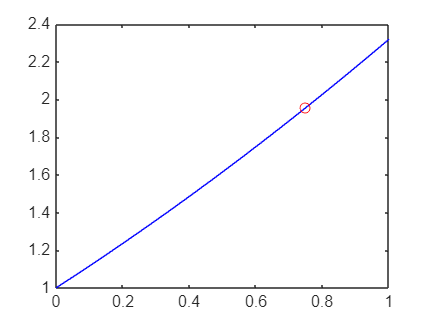


plot(xx,yy,'b',x1,y1,'ro')


error = exp(sin(0.75)) - y1

error = 0.0208

#### Polinomio de lagrange

function p=lagrange(x,y)
    n=length(x);
    p=zeros(1,n);
    for k=1:n
        num=poly(x([1:k-1,k+1:n]));
        den=polyval(num,x(k));
        L=num/den;
        p=p+y(k)*L;
    end
end

#### Spline Cubico Natural

function S=splinenatural(X,Y)
    N=length(X)-1; H=diff(X); E=diff(Y)./H;
    diagprinc=2*(H(1:N-1)+H(2:N)); diagsupinf=H(2:N-1);
    g0=0; gn=0;
    A=diag(diagprinc)+diag(diagsupinf,1)+diag(diagsupinf,-1);
    b=6*diff(E'); g=A\b;
    g=[g0 g' gn];
    for i=1:N
        S(i,1)=(g(i+1)-g(i))/(6*H(i));
        S(i,2)=g(i)/2;
        S(i,3)= E(i)-H(i)*(g(i+1)+2*g(i))/6;
        S(i,4)=Y(i);
        xx=linspace(X(i),X(i+1),100);
        yy=S(i,1)*(xx-X(i)).^3+S(i,2)*(xx-X(i)).^2+S(i,3)*(xx-X(i))+S(i,4);
        plot(xx,yy), hold on
    end
    grid on, hold off
end

#### Trapecio Compuesto

function [ItrapC]=trapComp(f,a,b,n)
    h=(b-a)/n ;
    x=[a:h:b];
    ItrapC=(h/2)*(f(a)+2*sum(f(x(2:length(x)-1)))+f(b));
end

#### Simpson 1/3 Compuesto

function [IsimpC]=simpsonC(f,a,b,n)
    h=(b-a)/n; %N es el numero de subintervalos
    x=[a:h:b];
    xpar=x(2:2:length(x)-1);
    ximpar=x(3:2:length(x)-2);
    IsimpC=(h/3)*(f(a)+4*sum(f(xpar))+2*sum(f(ximpar))+f(b));
end

#### Romberg

function [T,R]=romberg(fun,a,b,orden)
    interv=1;
    for j=1:orden
        T(j,1)=trapComp(fun,a,b,interv);
        interv=interv*2;
    end
    for k=2:orden
        for j=1:(orden-k+1)
            T(j,k)=(4^(k-1)*T(j+1,k-1)-T(j,k-1))/(4^(k-1)-1);
        end
    end
    R=T(1,orden);
end

#### Gaussnp

function G=gaussnp(f,a,b,n)
    %Aporte de alumnos del ciclo 2022-2 del curso de metodos numericos
    syms x
    %PRIMER PASO: Calcular el polinomio de Legendre de grado n
    lg=legendreP(n,x);
    dlg=matlabFunction(diff(lg,x));
    %SEGUNDO PASO: Calcular las raíces del polinomio de Legendre
    roots=double(vpasolve(lg==0));
    %TERCER PASO: Calcular los pesos de las raíces del polinomio de Legendre
    pesos=(2./((1-roots.^2).*dlg(roots).^2));
    %CUARTO PASO: Transformar los límites de la fxn
    syms t
    x=((b-a)*t+(a+b))/2;
    F=matlabFunction(f(x));
    %QUINTO PASO: Calcular el valor de la integral
    G=((b-a)/2)*sum(pesos.*(F(roots)));
end